**Ecole Centrale de Lyon**

**STItc3 - Conversion Analogique Numérique **

**BE1 : Conversion Uniforme**

**Groupe élèves**

NOM Prénom: MARCON Adèle

NOM Prénom: FRELECHOUX Chloé

**Groupe de TP : C1a2**

**Date : 19/12/2025**

**Numéro extrait :1**

## 1) Signal "analogique" $x$

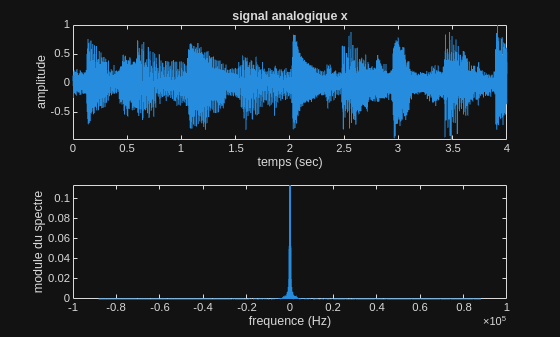

clear all;
close all;
clc;

% Chargement de data et nuscont la  fréquence d'échantillonnage (Hz) du signal "analogique"
load Extrait_1.mat; % Choix du signal 

x = data;           % signal
x = x/max(abs(x));  % normalisation x \in [-1;+1]

Tscont = 1/nuscont;                 % période d'echantillonnage
N = length(x);                      % taille du signal
tcont = (0:N-1)*Tscont;             % vecteur des temps "continus"
nucont = (-N/2:N/2-1)*nuscont/N;    % vecteur des fréquences (centré sur 0)

X = fftshift(Tscont*fft(x));        % spectre du signal (centré sur 0)

figure,
    subplot(211) 
        plot(tcont,x);
        axis tight;
        xlabel('temps (sec)');
        ylabel('amplitude');
        title('signal analogique x');
    subplot(212)
        plot(nucont,abs(X));
        xlabel('frequence (Hz)');
        ylabel('module du spectre');


if(1)   % mettre if(0) pour ne pas ecouter
    sound(x,nuscont);
    pause(2);
end

## 2) Echantillonnage : signal discret $x^*$

nus = 44100;        % fréquence d'échantillonnage du signal échantillonné (Hz)
Ts = 1/nus;         % période d'échantillonnage (sec)

**2) a) Ce filtre permet de respecter le théorème de Shannon**

- **Conception d'un filtre anti-repliement **

nuc = 17000;           % frequence de coupure (Hz)
ordre = 9;         % ordre du filtre
[B,A] = butter(ordre,2*pi*nuc,'s'); % calcul de la fonction de transfert du filtre

- **Analyse de la réponse fréquentielle du filtre**

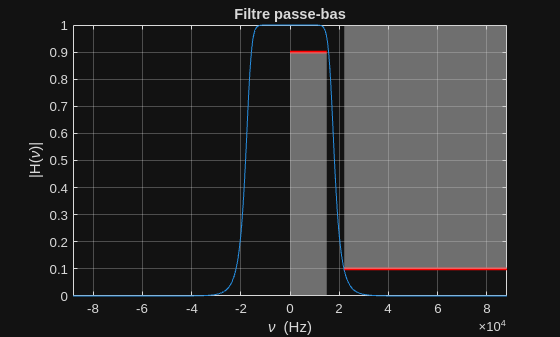

H = freqs(B,A,2*pi*nucont);

figure,
    plot(nucont,abs(H));
    hold on
    plot([0 15000],0.9*[1 1],'r','LineWidth',2)
    patch('xdata',[0 15000 15000 0], ...
        'ydata',[0.9 0.9 0 0],...
        'facecolor',[.8 .8 .8], ...
        'facealpha',.5,...
        'edgecolor','none');   
    plot([22050 nucont(end)],0.1*[1 1],'r','LineWidth',2)
    patch('xdata',[22050 nucont(end) nucont(end) 22050], ...
        'ydata',[0.1 0.1 1 1],...
        'facecolor',[.8 .8 .8], ...
        'facealpha',.5,...
        'edgecolor','none');  
    axis([nucont(1) nucont(end) 0 1])
    xlabel('\nu (Hz)');
    ylabel('|H(\nu)|');
    title('Filtre passe-bas')
    grid on

- **Application du filtre à x **

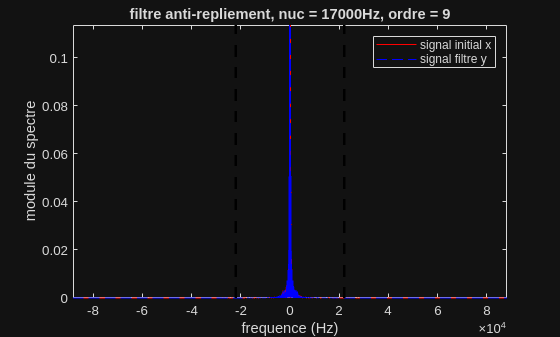

y = lsim(tf(B,A),x,tcont);
Y = fftshift(Tscont*fft(y));

figure,
    plot(nucont,abs(X),'r',nucont,abs(Y),'b--')
    hold on
    plot([nus/2 nus/2],[0 max(abs(X))],'--k','linewidth',2)        
    plot([-nus/2 -nus/2],[0 max(abs(X))],'--k','linewidth',2);
    axis tight;
    legend('signal initial x','signal filtre y');
    xlabel('frequence (Hz)');
    ylabel('module du spectre');
    title(['filtre anti-repliement, nuc = ',num2str(nuc),'Hz, ordre = ',num2str(ordre)]);

- **Echantillonnage**

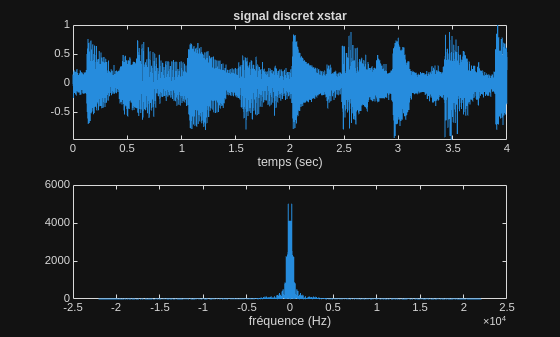

rse = round(nuscont/nus);
xstar = y(1:rse:end);         % sous-échantillonnage de y
N = length(xstar);
t = (0:N-1)*Ts;
nu = (-N/2:N/2-1)*nus/N;
Xstar = fftshift(fft(xstar));

figure,
    subplot(211)
    plot(t,xstar)
    axis tight
    xlabel('temps (sec)');
    title('signal discret xstar');
    subplot(212)
    plot(nu,abs(Xstar))
    xlabel('fréquence (Hz)')


if(1)
    sound(xstar,nus);
    pause(2);
end

3) À l'oreille, il n'y a pas de différence entre x et xstar. En observant les spectres, on n'observe pas de différence notable (sauf un rapport d'amplitude).

## 3) Quantification uniforme : signal numérique $\tilde{x}$ 

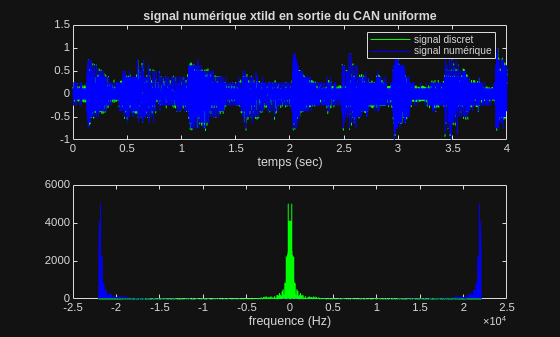

Nbit = 3;                                                   % nombre de bits de quantification
q = (floor(max(xstar))-ceil(min(xstar)))/(2^Nbit);          % pas de quantification
xtild = q*round(xstar./q);                                  % signal numérique   
Xtild = fft(xtild);                                         % spectre du signal numérique    

figure,
    subplot(211)
    plot(t,xstar,'g',t,xtild,'b')
    legend('signal discret','signal numérique')
    xlim([t(1) t(end)])
    xlabel('temps (sec)')
    title('signal numérique xtild en sortie du CAN uniforme');
    subplot(212)
    plot(nu,abs(Xtild),'b',nu,abs(Xstar),'g')
    xlabel('frequence (Hz)')


if(0)
    sound(xtild,nus);
    pause(2);
end

5) Pour Nbit = 3, à l'oreille on entend bruit de fond (grésillement, bruit d'ambiance). Sur le spectre on voit que le signal discret possède de nouvelles composantes haute fréquence et de différences notables sur le graphique temporel.

À partir de Nbit ~ 7, on ne remarque plus de différence à l'oreille entre xstar et et xtild

## 4) Analyse de l'erreur de quantification $e^*$

-  **Erreur de quantification**

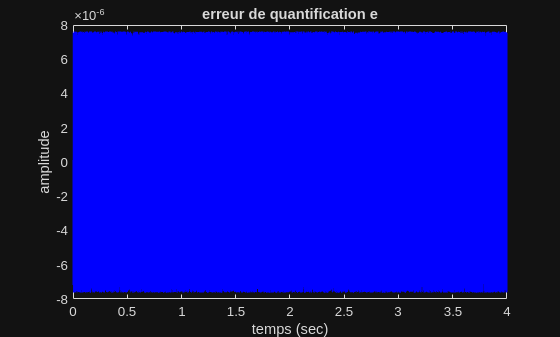

equant = xtild-xstar; % erreur de quantification
figure,
    plot(t,equant,'b')
    xlim([t(1) t(end)])
    xlabel('temps (sec)')
    ylabel('amplitude')
    title('erreur de quantification e')

- **Densité spectrale de puissance**

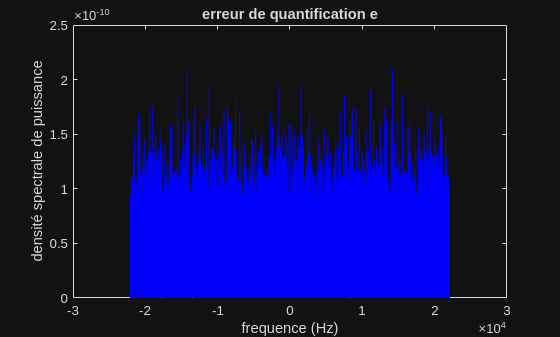

Sequant = fftshift(1/N*abs(fft(equant)).^2);
figure,
    plot(nu,Sequant,'b')
    xlabel('frequence (Hz)')
    ylabel('densité spectrale de puissance')
    title('erreur de quantification e')

7) Modèle du cours: bruit blanc de densité spectrale constante. Ici on observe une erreur dont la valeur moyenne est constante. C'est donc la réalisation d'un processus aléatoire (bruit blanc). Cela correspond donc bien au modèle adopté en cours

- **Loi de probabilité**

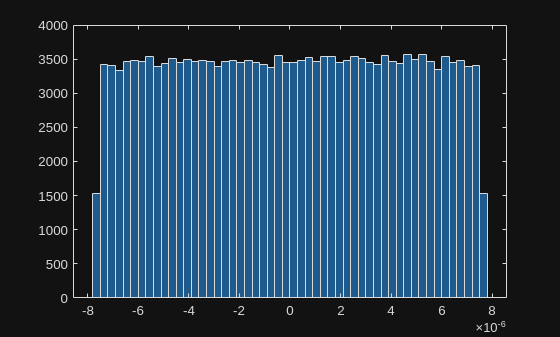

histogram(equant) % utiliser la fonction histogram

La distribution est effectivement constante donc on a bien une loi uniforme (modèle adopté en cours).

- **Relation coût-performance**

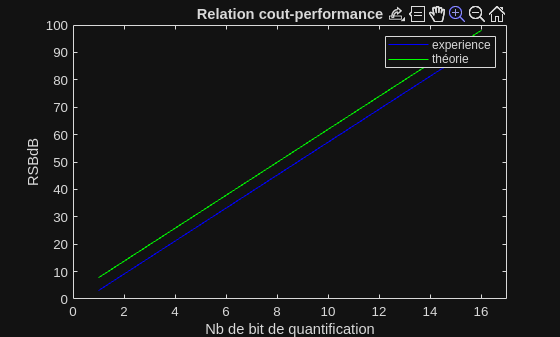

vNbit = (1:16);       % nombre de bits de quantification
for ii = 1:length(vNbit)
    q = (floor(max(xstar))-ceil(min(xstar)))/(2^vNbit(ii));          % pas de quantification
    xtild = q*round(xstar./q);                                      % signal numérique   
    equant = xtild-xstar;      % erreur de quantification
    Px = sum(xstar.^2)/length(xstar);
    Pe = (q^2)/12;
    RSBdB(ii) = 10*log10(Px/Pe);   % rapport signal sur bruit
end

figure,
    plot(vNbit,RSBdB,'b',vNbit,1.76+6.02*vNbit,'g')
    legend('experience','théorie')
    xlim([0 max(vNbit)+1])
    xlabel('Nb de bit de quantification')
    ylabel('RSBdB')
    title('Relation cout-performance')

9) On observe bien une cohérence avec le modèle grâce à la pente mais il y a un décalage d'ordonnée à l'origine. Cela s'explique par la définition de Px dans le modèle du cours où l'on utilise une fonction sinusoïdale pour xstar (Ici avec l'extrait audio on aclairement pas un extrait sinusoïdal).